# Solving Physics Problems with Galerkin's Method

Many physical phenomena can be accurately described via differential equations.  These differential equations are often difficult, if not impossible to solve exactly and so must be approximated.

Let's consider the Poisson differential equation, which is used to describe a wide variety of physics including heat transfer, electrostatics, and gravity.  We'll define this equation over a finite domain and impose conditions for the solution on the boundaries of the domain -- this is often called a *boundary value problem.*


$$\frac{d^2 u}{dx^2 }+f=0$$


Let $\Omega =\left\lbrack 0,1\right\rbrack$


$$u\left(1\right)=g$$



$$\frac{du}{dx}(0)=h$$


Now, *this* boundary value problem is simple enough that we *are* able to solve it exactly using Matlab's `dsolve` routine.

function exactSolution = ExactPoissonSolution( f, g, h, domain )
syms u(x)
eqn = diff( u, x, 2 ) + f == 0;
Du = diff( u, x, 1 );
cond = [  u( domain(2) ) == g, ...
    Du( domain(1) ) == h ];
U(x) = dsolve( eqn, cond );

exactSolution.f = f;
exactSolution.eqn = eqn;
exactSolution.cond = cond;
exactSolution.domain = domain;
exactSolution.U = simplify( U, Steps=10 );
end

Which we can then solve as

syms x f(x) g h
domain = sym( "X", [1,2] )

$$domain = \left[\begin{array}{cc} X_{1} & X_{2} \end{array}\right]$$

u = ExactPoissonSolution( f, g, h, domain ).U

$$u(x) = g-h\,\left(X_{2}-x\right)-\left(X_{2}-x\right)\,\int_{X_{2}}^{X_{1}}f\left(y\right)\mathrm{d}y+\int_{X_{2}}^{x}\left(-\int_{X_{2}}^{v}f\left(y\right)\mathrm{d}y\right)\mathrm{d}v$$

Into which we can then plug values corresponding to a specific configuration we might be investigating into and recover the solution to the configuration:

figure
f1 = x^2;
g1 = 0;
h1 = 0;
domain1 = [0, 1];
U(x) = subs( u, [f, g, h, domain], [f1, g1, h1, domain1] )

$$U(x) = \frac{1}{12}-\frac{x^{4}}{12}$$

U(x) = ExactPoissonSolution( f1, g1, h1, domain1 ).U

$$U(x) = \frac{1}{12}-\frac{x^{4}}{12}$$

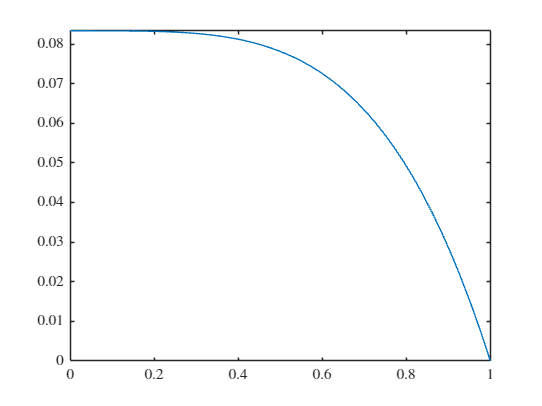

fplot( U, [0 1] )

Again, it is typically not possible to do this on real problems encountered in engineering, but this will allow us to compare our approximate solutions against exact solutions, thus evaluating the efficacy of Galerkin's Method.

## Solving the Poisson Equation with Galerkin's Method

We can rearrange the strong form of the Poisson equation as:


$$\frac{d^2 u}{dx^2 }=-f$$


We'll interpret this statement as "find the best representation of $-f$in the second derivative of $u$" or "find $u$ such that it's second derivative is the best representation of negative $-f$".  We recognize these statements as being similar to those regarding the change of basis operator, for which we derived the mnemonic device "To To to, To From from" or, $\left\langle T,T\right\rangle \mathrm{t}=\left\langle T,F\right\rangle \mathrm{f}$.  Following this mnemonic, or at least the $\left\langle T,T\right\rangle =\left\langle T,F\right\rangle$portion we compose a weak form as:


$$\left\langle \frac{d^2 u}{{\mathrm{dx}}^2 },\frac{d^2 u}{{\mathrm{dx}}^2 }\right\rangle =\left\langle \frac{{\mathrm{d}}^2 u}{{\mathrm{dx}}^2 },-f\right\rangle$$


But recognize that the mnemonic isn't rigorous.  In fact, the more accurate statement is to say that in order to determine how well $-f$ is represented in the second derivative of $u$, we need to be able to make a measurement i.e., compare inner products.  So we take the inner product between $-f$and $\frac{d^2 u}{{\mathrm{dx}}^2 }$ and compare it to the inner product of $\frac{d^2 u}{{\mathrm{dx}}^2 }$ and itself (i.e., $\frac{d^2 u}{{\mathrm{dx}}^2 }$) .  But for now, let's just use the mnemonic device of this being similar to a change of basis to aid us in formulating weak forms.

Now let's introduce an approximation of the solution, $\tilde{u} \approx u$, that we define to be a polynomial function i.e., $\tilde{u} \left(x\right)=a_0 x^0 +a_1 x^1 +\cdots +a_{n-1} x^{n-1} +a_n x^n$.  Recall that the derivative of a polynomial function is also a polynomial function and that we can that we can represent these polynomials in basis form


$$\tilde{u} =\sum_{i=0}^n {\mathbf{a}}_i {\mathbf{A}}_i$$



$$\frac{{\mathrm{d}}^2 \tilde{u} }{{\mathrm{dx}}^2 }=\sum_{i=0}^n {\mathbf{a}}_i \left(\frac{d}{\mathrm{dx}}{\mathbf{A}}_i \right)=\sum_{i=0}^n {\mathbf{c}}_i {\mathbf{C}}_i$$


Thus we can rewrite the weak form as:


$$\left\langle \sum_{i=0}^m {\mathbf{c}}_i {\mathbf{C}}_i ,\sum_{j=0}^n {\mathbf{c}}_j {\mathbf{C}}_j \right\rangle =\left\langle \sum_{i=0}^m {\mathbf{c}}_i {\mathbf{C}}_i ,-f\right\rangle$$



$$\sum_{i=0}^m {\mathbf{c}}_i \left\langle {\mathbf{C}}_i ,\sum_{j=0}^n {\mathbf{c}}_j {\mathbf{C}}_j \right\rangle =\sum_{i=0}^m {\mathbf{c}}_i \left\langle {\mathbf{C}}_i ,-f\right\rangle$$



$$\left\langle {\mathit{\mathbf{C}}}_i ,\sum_{j=0}^n {\mathbf{c}}_j {\mathit{\mathbf{C}}}_j \right\rangle =\left\langle {\mathit{\mathbf{C}}}_i ,-f\right\rangle$$



$$\sum_{i=0,\;j=0}^{m,\;n} {\mathbf{c}}_j \left\langle {\mathit{\mathbf{C}}}_i ,{\mathit{\mathbf{C}}}_j \right\rangle =-\left\langle {\mathit{\mathbf{C}}}_i ,f\right\rangle$$


Or, written in matrix form:


$$\left\lbrack \begin{array}{ccc}
\left\langle C_1 ,C_1 \right\rangle  & \cdots  & \left\langle C_1 ,C_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle C_m ,C_1 \right\rangle  & \cdots  & \left\langle C_m ,C_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
\vdots \\
c_n 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
\left\langle C_1 ,f\right\rangle \\
\vdots \\
\left\langle C_n ,f\right\rangle 
\end{array}\right\rbrack$$


Next we consider the Neumann boundary condition $\frac{\textrm{du}}{\textrm{dx}}\left(0\right)=h$, which we can again represent in our approximate form $\frac{\mathrm{d}\tilde{u} }{\textrm{dx}}\left(0\right)=h$ and in weak form as:


$$\left\langle \frac{\textrm{du}}{\textrm{dx}}\left(0\right),\frac{\textrm{du}}{\textrm{dx}}\left(0\right)\right\rangle =\left\langle \frac{\textrm{du}}{\textrm{dx}}\left(0\right),h\right\rangle$$



$$\left\lbrack \begin{array}{ccc}
\left\langle B_1 ,B_1 \right\rangle  & \cdots  & \left\langle B_1 ,B_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle B_m ,B_1 \right\rangle  & \cdots  & \left\langle B_m ,B_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
b_1 \\
\vdots \\
b_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left\langle B_1 ,h\right\rangle \\
\vdots \\
\left\langle B_n ,h\right\rangle 
\end{array}\right\rbrack$$


Finally we consider the Dirichlet boundary condition $u\left(1\right)=g$, which we can, once again, represent in our approximate form $\tilde{u} \left(1\right)=g$ and in weak form as:


$$\left\langle u\left(1\right),u\left(1\right)\right\rangle =\left\langle u\left(1\right),g\right\rangle$$



$$\left\lbrack \begin{array}{ccc}
\left\langle A_1 ,A_1 \right\rangle  & \cdots  & \left\langle A_1 ,A_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle A_m ,A_1 \right\rangle  & \cdots  & \left\langle A_m ,A_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
\vdots \\
a_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left\langle A_1 ,g\right\rangle \\
\vdots \\
\left\langle A_n ,g\right\rangle 
\end{array}\right\rbrack$$


Now we have three weak form systems:


$$\left\langle \frac{d^2 u}{{\mathrm{dx}}^2 },\frac{d^2 u}{{\mathrm{dx}}^2 }\right\rangle =\left\langle \frac{{\mathrm{d}}^2 u}{{\mathrm{dx}}^2 },-f\right\rangle$$



$$\left\langle \frac{\textrm{du}\left(0\right)}{\textrm{dx}},\frac{\textrm{du}\left(0\right)}{\textrm{dx}}\right\rangle =\left\langle \frac{\textrm{du}\left(0\right)}{\textrm{dx}},h\right\rangle$$



$$\left\langle u\left(1\right),u\left(1\right)\right\rangle =\left\langle u\left(1\right),g\right\rangle$$


Which we can combine into a single equation as:


$$\left\langle \frac{d^2 u}{{\mathrm{dx}}^2 },\frac{d^2 u}{{\mathrm{dx}}^2 }\right\rangle +\left\langle \frac{\mathrm{du}\left(0\right)}{\mathrm{dx}},\frac{\mathrm{du}\left(0\right)}{\mathrm{dx}}\right\rangle +\left\langle u\left(1\right),u\left(1\right)\right\rangle =\left\langle \frac{{\mathrm{d}}^2 u}{{\mathrm{dx}}^2 },-f\right\rangle +\left\langle \frac{\mathrm{du}\left(0\right)}{\mathrm{dx}},h\right\rangle +\left\langle u\left(1\right),g\right\rangle$$



$$\left\lbrack \begin{array}{ccc}
\left\langle C_1 ,C_1 \right\rangle  & \cdots  & \left\langle C_1 ,C_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle C_m ,C_1 \right\rangle  & \cdots  & \left\langle C_m ,C_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
\vdots \\
c_n 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
\left\langle B_1 ,B_1 \right\rangle  & \cdots  & \left\langle B_1 ,B_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle B_m ,B_1 \right\rangle  & \cdots  & \left\langle B_m ,B_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
b_1 \\
\vdots \\
b_n 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
\left\langle A_1 ,A_1 \right\rangle  & \cdots  & \left\langle A_1 ,A_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle A_m ,A_1 \right\rangle  & \cdots  & \left\langle A_m ,A_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
\vdots \\
a_n 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
\left\langle C_1 ,f\right\rangle \\
\vdots \\
\left\langle C_n ,f\right\rangle 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\left\langle B_1 ,h\right\rangle \\
\vdots \\
\left\langle B_n ,h\right\rangle 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\left\langle A_1 ,g\right\rangle \\
\vdots \\
\left\langle A_n ,g\right\rangle 
\end{array}\right\rbrack$$


And recall that since the basis functions for each of the weak forms are simply derivatives of the same basis we have $\mathbf{a}=\mathbf{b}=\mathbf{c}$:


$$\begin{array}{l}
\tilde{u} =a_0 A_0 +a_1 A_1 +\cdots a_{n-1} A_{n-1} +a_n A_n \\
\frac{\mathrm{d}\tilde{u} }{\textrm{dx}}=a_0 \left(\frac{\mathrm{d}}{\textrm{dx}}A_0 \right)+a_1 \left(\frac{\mathrm{d}}{\textrm{dx}}A_1 \right)+\cdots a_{n-1} \left(\frac{\mathrm{d}}{\textrm{dx}}A_{n-1} \right)+a_n \left(\frac{\mathrm{d}}{\textrm{dx}}A_n \right)\\
\frac{{\mathrm{d}}^2 \tilde{u} }{{\textrm{dx}}^2 }=a_0 \left(\frac{{\mathrm{d}}^2 }{{\textrm{dx}}^2 }A_0 \right)+a_1 \left(\frac{{\mathrm{d}}^2 }{{\textrm{dx}}^2 }A_1 \right)+\cdots a_{n-1} \left(\frac{{\mathrm{d}}^2 }{{\textrm{dx}}^2 }A_{n-1} \right)+a_n \left(\frac{{\mathrm{d}}^2 }{{\textrm{dx}}^2 }A_n \right)
\end{array}$$


For example:

clear

x = sym( "x" );
basis_family = "Lagrange";
domain = [0 1];
degree = 4;

basis = PolynomialBasisFunction( basis_family, degree, x, domain );
a = [1; 0; 2; 0; 3];
d0P = expand( transpose(a) * diff( basis, x, 0 ) )

$$d0P = \frac{512\,x^{4}}{3}-\frac{992\,x^{3}}{3}+\frac{592\,x^{2}}{3}-\frac{106\,x}{3}+1$$

d1P = expand( transpose(a) * diff( basis, x, 1 ) )

$$d1P = \frac{2048\,x^{3}}{3}-992\,x^{2}+\frac{1184\,x}{3}-\frac{106}{3}$$

d2P = expand( transpose(a) * diff( basis, x, 2 ) )

$$d2P = 2048\,x^{2}-1984\,x+\frac{1184}{3}$$

d3P = expand( transpose(a) * diff( basis, x, 3 ) )

$$d3P = 4096\,x-1984$$

d4P = expand( transpose(a) * diff( basis, x, 4 ) )

$$d4P = 4096$$

and can thus simplify as:


$$\left(\left\lbrack \begin{array}{ccc}
\left\langle C_1 ,C_1 \right\rangle  & \cdots  & \left\langle C_1 ,C_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle C_m ,C_1 \right\rangle  & \cdots  & \left\langle C_m ,C_n \right\rangle 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
\left\langle B_1 ,B_1 \right\rangle  & \cdots  & \left\langle B_1 ,B_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle B_m ,B_1 \right\rangle  & \cdots  & \left\langle B_m ,B_n \right\rangle 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
\left\langle A_1 ,A_1 \right\rangle  & \cdots  & \left\langle A_1 ,A_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle A_m ,A_1 \right\rangle  & \cdots  & \left\langle A_m ,A_n \right\rangle 
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
a_1 \\
\vdots \\
a_n 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
\left\langle C_1 ,f\right\rangle +\left\langle B_1 ,h\right\rangle +\left\langle A_1 ,g\right\rangle \\
\vdots \\
\left\langle C_n ,f\right\rangle +\left\langle B_n ,h\right\rangle +\left\langle A_n ,g\right\rangle 
\end{array}\right\rbrack$$



$$\left(\left\lbrack \begin{array}{ccc}
\left\langle C_1 ,C_1 \right\rangle +\left\langle B_1 ,B_1 \right\rangle +\left\langle A_1 ,A_1 \right\rangle  & \cdots  & \left\langle C_1 ,C_n \right\rangle +\left\langle B_1 ,B_n \right\rangle +\left\langle A_1 ,A_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle C_m ,C_1 \right\rangle +\left\langle B_m ,B_1 \right\rangle +\left\langle A_m ,A_1 \right\rangle  & \cdots  & \left\langle C_m ,C_n \right\rangle +\left\langle B_m ,B_n \right\rangle +\left\langle A_m ,A_n \right\rangle 
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
a_1 \\
\vdots \\
a_n 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
\left\langle C_1 ,f\right\rangle +\left\langle B_1 ,h\right\rangle +\left\langle A_1 ,g\right\rangle \\
\vdots \\
\left\langle C_n ,f\right\rangle +\left\langle B_n ,h\right\rangle +\left\langle A_n ,g\right\rangle 
\end{array}\right\rbrack$$


Putting this together

clear
x = sym( "x" );
f = 5;
g = 1;
h = 1;
basis_family = "Monomial";
degree = 4;
domain = [0, 1];

U(x) = expand( ExactPoissonSolution( f, g, h, domain ).U )

$$U(x) = -\frac{5\,x^{2}}{2}+x+\frac{5}{2}$$


basis = @(deriv) diff( PolynomialBasisFunction( basis_family, degree, x, domain ), x, deriv )

basis = function_handle with value:
    @(deriv)diff(PolynomialBasisFunction(basis_family,degree,x,domain),x,deriv)



% Governing equation
MG = int( basis(2) .* transpose( basis(2) ), domain )

$$MG = \left[\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 4 & 6 & 8\\ 0 & 0 & 6 & 12 & 18\\ 0 & 0 & 8 & 18 & \frac{144}{5} \end{array}\right]$$

FG = -int( basis(2) * f, domain )

$$FG = \left[\begin{array}{c} 0\\ 0\\ -10\\ -15\\ -20 \end{array}\right]$$

% Dirichlet boundary condition
MD = simplify( basis(0) .* transpose( basis(0) ), Steps=10 )

$$MD = \left[\begin{array}{ccccc} 1 & x & x^{2} & x^{3} & x^{4}\\ x & x^{2} & x^{3} & x^{4} & x^{5}\\ x^{2} & x^{3} & x^{4} & x^{5} & x^{6}\\ x^{3} & x^{4} & x^{5} & x^{6} & x^{7}\\ x^{4} & x^{5} & x^{6} & x^{7} & x^{8} \end{array}\right]$$

MD = subs( MD, symvar( basis(0) ), domain(2) )

$$MD = \left[\begin{array}{ccccc} 1 & 1 & 1 & 1 & 1\\ 1 & 1 & 1 & 1 & 1\\ 1 & 1 & 1 & 1 & 1\\ 1 & 1 & 1 & 1 & 1\\ 1 & 1 & 1 & 1 & 1 \end{array}\right]$$

FD = simplify( basis(0) * g, Steps=10 )

$$FD = \left[\begin{array}{c} 1\\ x\\ x^{2}\\ x^{3}\\ x^{4} \end{array}\right]$$

FD = subs( FD, symvar( basis(0) ), domain(2) )

$$FD = \left[\begin{array}{c} 1\\ 1\\ 1\\ 1\\ 1 \end{array}\right]$$

% Neumann boundary condition
MN = simplify( basis(1) .* transpose( basis(1) ), Steps=10 )

$$MN = \left[\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 2\,x & 3\,x^{2} & 4\,x^{3}\\ 0 & 2\,x & 4\,x^{2} & 6\,x^{3} & 8\,x^{4}\\ 0 & 3\,x^{2} & 6\,x^{3} & 9\,x^{4} & 12\,x^{5}\\ 0 & 4\,x^{3} & 8\,x^{4} & 12\,x^{5} & 16\,x^{6} \end{array}\right]$$

MN = subs( MN, symvar( basis(1) ), domain(1) )

$$MN = \left[\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

FN = simplify( basis(1) * h, Steps=10 )

$$FN = \left[\begin{array}{c} 0\\ 1\\ 2\,x\\ 3\,x^{2}\\ 4\,x^{3} \end{array}\right]$$

FN = subs( FN, symvar( basis(1) ), domain(1) )

$$FN = \left[\begin{array}{c} 0\\ 1\\ 0\\ 0\\ 0 \end{array}\right]$$

% Fully assembled linear system
M = MG + MD + MN

$$M = \left[\begin{array}{ccccc} 1 & 1 & 1 & 1 & 1\\ 1 & 2 & 1 & 1 & 1\\ 1 & 1 & 5 & 7 & 9\\ 1 & 1 & 7 & 13 & 19\\ 1 & 1 & 9 & 19 & \frac{149}{5} \end{array}\right]$$

F = FG + FD + FN

$$F = \left[\begin{array}{c} 1\\ 2\\ -9\\ -14\\ -19 \end{array}\right]$$


coeffs = M \ F

$$coeffs = \left[\begin{array}{c} \frac{5}{2}\\ 1\\ -\frac{5}{2}\\ 0\\ 0 \end{array}\right]$$

u(x) = expand( transpose( coeffs ) * basis(0) )

$$u(x) = -\frac{5\,x^{2}}{2}+x+\frac{5}{2}$$


displayFormula( "u == U" )

$$-\frac{5\,x^{2}}{2}+x+\frac{5}{2}=-\frac{5\,x^{2}}{2}+x+\frac{5}{2}$$

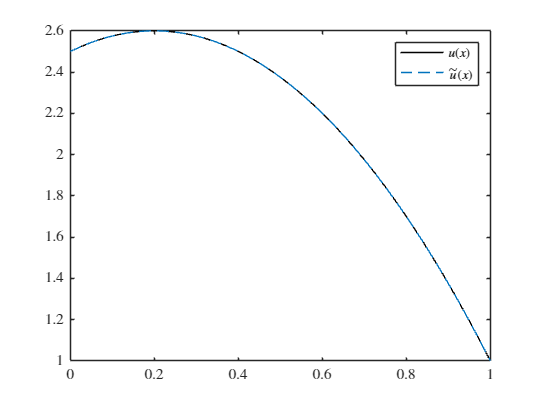


figure
hold on
fplot( U, domain, Color="k", DisplayName="$$u(x)$$" )
fplot( u, domain, LineStyle="--", SeriesIndex=1, DisplayName="$$\tilde{u}(x)$$" )
legend( Interpreter="latex" )

As we see, we've solved the Poisson equation with the Galerkin method and arrived at the exact solution. Let's take our work above and develop a set of functions that solves the Poisson equation:

function [u, M, F, basis, d] = PoissonEquation( basis_family, degree, domain, f, g, h )
variate = symvar(f);
basis = @(deriv) diff( PolynomialBasisFunction( basis_family, degree, variate, domain ), variate, deriv );
[M, F] = ApplyGoverningEquation( basis, domain, f );
[M, F] = ApplyBoundaryConditions( M, F, basis, domain, g, h );
d = M \ F;
u = symfun( transpose( d ) * basis(0), variate );
u = simplify( u, Steps=10 );

    function [M, F] = ApplyGoverningEquation( basis, domain, distributed_load )
        M = int( basis(2) .* transpose( basis(2) ), domain );
        F = -int( basis(2) * distributed_load, domain );
    end

    function [M, F] = ApplyBoundaryConditions( M, F, basis, domain, g, h )
        [MD, FD] = DirichletBoundaryCondition( basis, domain, g );
        [MN, FN] = NeumannBoundaryCondition( basis, domain, h );
        M = M + MD + MN;
        F = F + FD + FN;
    end

    function [M, F] = DirichletBoundaryCondition( basis, domain, g )
        M = subs( basis(0) .* transpose( basis(0) ), symvar( basis(0) ), domain(2) );
        F = subs( basis(0) * g, symvar( basis(0) ), domain(2) );
    end

    function [M, F] = NeumannBoundaryCondition( basis, domain, h )
        M = subs( basis(1) .* transpose( basis(1) ), symvar( basis(1) ), domain(1) );
        F = subs( basis(1) * h, symvar( basis(1) ), domain(1) );
    end
end

Take a moment to notice how concise the above routine is

clear
x = sym( "x" );
f(x) = 5*x^0;
g = 1;
h = 1;
basis_family = "Monomial";
degree = 4;
domain = [0, 1];
u(x) = PoissonEquation( basis_family, degree, domain, f, g, h )

$$u(x) = -\frac{5\,x^{2}}{2}+x+\frac{5}{2}$$

Note that in the previous example we were able to arrive at the exact solution because the exact solution happens to be polynomial and the polynomial basis we used was of sufficiently high degree to recover the polynomial solution.  If, for example, the polynomial basis degree was too low the Galerkin method would only produce the closest polynomial of that degree to the exact solution.  Or if the forcing function$f\left(x\right)$ was not polynomial then the exact solution wouldn't be polynomial either and the Galerkin method would only produce *the closest polynomial* of our chosen degree to the exact solution, i.e., the best approximation of the solution within our chosen basis.

Let's demonstrate a case where the polynomial degree is too low to recover an exact polynomial solution.

clear

x = sym( "x", "real" );
f(x) = 5*x^0;
g = 1;
h = 1;
domain = [0, 1];
degree = 1;
basis_family = "Monomial";

U = ExactPoissonSolution( f, g, h, domain ).U

$$U(x) = \frac{5}{2}-\frac{x\,\left(5\,x-2\right)}{2}$$

u = PoissonEquation( basis_family, degree, domain, f, g, h )

$$u(x) = x$$


l2_error = ComputeL2Error( U, u, domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 1.825741858350554$$

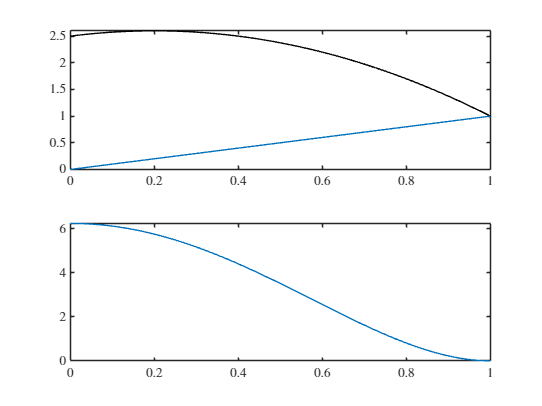


figure
subplot( 2, 1, 1 )
hold on
fplot( U, domain, Color="k" )
fplot( u, domain, SeriesIndex=1 )

subplot( 2, 1, 2 )
fplot( simplify( U - u )^2, domain )

Note that while our approximation looks completely wrong, remember that we're enforcing the boundary conditions, $\frac{\textrm{du}}{\textrm{dx}}\left(0\right)=1$and $\mathrm{u}\left(1\right)=1$, which we can see are being respected in the solution.  Next we consider an example of a non-polynomial forcing function, resulting in a non-polynomial solution:

clear

x = sym( "x", "real" );
f(x) = sin(2*pi*x);
g = 1;
h = 0;
domain = [0, 1];
degree = 3;
basis_family = "Monomial";

U = ExactPoissonSolution( f, g, h, domain ).U

$$U(x) = \frac{\frac{\sin\left(2\,\pi \,x\right)}{4}-\pi \,\left(\frac{x}{2}-\frac{1}{2}\right)}{\pi^{2}}+1$$

u = PoissonEquation( basis_family, degree, domain, f, g, h )

$$u(x) = \frac{x^{3}-\frac{3\,x^{2}}{2}+\frac{1}{2}}{\pi }+1$$


l2_error = ComputeL2Error( U, u, domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.007167415830688885$$

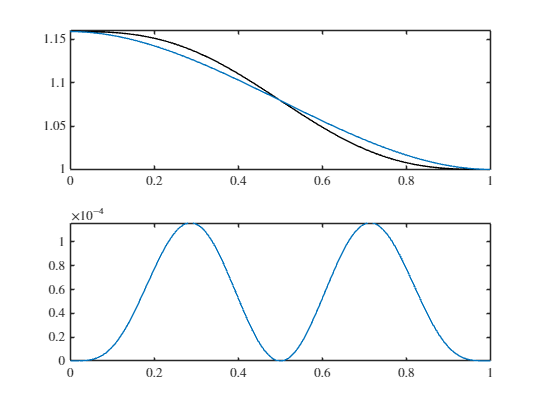


figure
subplot( 2, 1, 1 )
hold on
fplot( U, domain, Color="k" )
fplot( u, domain, SeriesIndex=1 )

subplot( 2, 1, 2 )
fplot( simplify( U - u )^2, domain )

## Solving the Heat Equation with Galerkin's Method

With this solution framework in place, we find it's almost trivial to solve other partial differential equations.  For example, consider the steady-state Heat Equation, which is only slightly different from the Poisson equation:


$$k\frac{{\mathrm{d}}^2 T}{{\textrm{dx}}^2 }=-q$$


With the following problem parameters

Let $\Omega =\left\lbrack 0,1\right\rbrack$


$$\frac{\textrm{dT}}{\textrm{dx}}\left(0\right)=h$$



$$T\left(1\right)=g$$


The analytic solution is:

function exactSolution = ExactHeatSolution( thermal_conductivity, internal_heat_flux, prescribed_temperature, boundary_heat_flux, domain )
syms u(x)
eqn = thermal_conductivity * diff( u, x, 2 ) + internal_heat_flux == 0;
Du = diff( u, x, 1 );
cond = [  u( domain(2) ) == prescribed_temperature, ...
    Du( domain(1) ) == boundary_heat_flux ];
U(x) = dsolve( eqn, cond );

exactSolution.f = internal_heat_flux;
exactSolution.eqn = eqn;
exactSolution.cond = cond;
exactSolution.domain = domain;
exactSolution.U = simplify( U, Steps=10 );
end

And to construct our weak form we again think about what we want to do: "find $T$ such that $k\frac{d^2 T}{{\mathrm{dx}}^2 }$ is the best representation of $-q$".  So again, using our mnemonic we have:


$$\left\langle k\frac{{\mathrm{d}}^2 T}{{\mathrm{dx}}^2 },\;k\frac{{\mathrm{d}}^2 T}{{\mathrm{dx}}^2 }\right\rangle =\left\langle k\frac{{\mathrm{d}}^2 T}{{\mathrm{dx}}^2 },-q\right\rangle$$


And similarly for the boundary conditions:

"find $T$ such that $\frac{\mathrm{dT}}{\mathrm{dx}}$ is the best representation of $h$ at $x=0$"


$${\left\langle \frac{dT}{\mathrm{dx}},\frac{dT}{\mathrm{dx}}\right\rangle }_{x=0} ={\left\langle \frac{dT}{\mathrm{dx}},h\right\rangle }_{x=0}$$


"find $T$ such that $T$ is the best representation of $g$ at $x=1$".


$${\left\langle T,T\right\rangle }_{x=1} ={\left\langle T,g\right\rangle }_{x=1}$$


function [u, M, F, basis, d] = HeatEquation( basis_family, degree, domain, thermal_conductivity, q, g, h )
variate = symvar(q);
basis = @(deriv) diff( PolynomialBasisFunction( basis_family, degree, variate, domain ), variate, deriv );
[M, F] = ApplyGoverningEquation( basis, domain, thermal_conductivity, q );
[M, F] = ApplyBoundaryConditions( M, F, basis, domain, g, h );
d = M \ F;
u = symfun( transpose( d ) * basis(0), variate );
u = simplify( u, Steps=10 );

    function [M, F] = ApplyGoverningEquation( basis, domain, thermal_conductivity, distributed_load )
        M = int( ( thermal_conductivity * basis(2) ) .* ( thermal_conductivity * transpose( basis(2) ) ), domain );
        F = -int( ( thermal_conductivity * basis(2) ) * distributed_load, domain );
    end

    function [M, F] = ApplyBoundaryConditions( M, F, basis, domain, g, h )
        [MD, FD] = DirichletBoundaryCondition( basis, domain, g );
        [MN, FN] = NeumannBoundaryCondition( basis, domain, h );
        M = M + MD + MN;
        F = F + FD + FN;
    end

    function [M, F] = DirichletBoundaryCondition( basis, domain, g )
        M = subs( basis(0) .* transpose( basis(0) ), symvar( basis(0) ), domain(2) );
        F = subs( basis(0) * g, symvar( basis(0) ), domain(2) );
    end

    function [M, F] = NeumannBoundaryCondition( basis, domain, h )
        M = subs( basis(1) .* transpose( basis(1) ), symvar( basis(1) ), domain(1) );
        F = subs( basis(1) * h, symvar( basis(1) ), domain(1) );
    end
end

And an example

clear

x = sym( "x", "real" );
thermal_conductivity = 100;
q(x) = 5*x^0;
g = 293.15;
h = 0;
domain = [-12, 12];
degree = 3;
basis_family = "Monomial";

T = ExactHeatSolution( thermal_conductivity, q, g, h, domain ).U

$$T(x) = \frac{6079}{20}-\frac{x\,\left(x+24\right)}{40}$$

t = HeatEquation( basis_family, degree, domain, thermal_conductivity, q, g, h )

$$t(x) = \frac{6151}{20}-\frac{72\,{\left(\frac{x}{24}+\frac{1}{2}\right)}^{2}}{5}$$


l2_error = ComputeL2Error( T, t, domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0$$

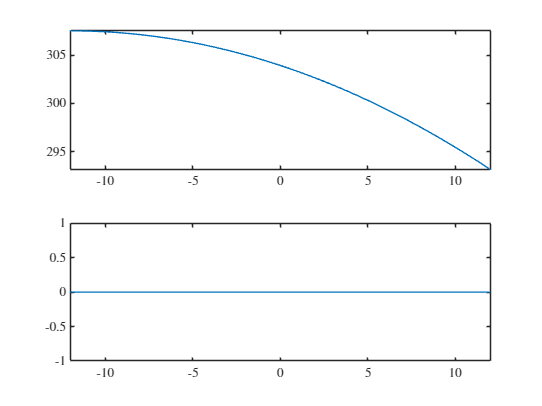


figure
subplot( 2, 1, 1 )
hold on
fplot( T, domain, Color="k" )
fplot( t, domain, SeriesIndex=1 )

subplot( 2, 1, 2 )
fplot( simplify( T - t )^2, domain )

## Solving the Euler–Bernoulli equation with Galerkin's Method

Next we consider the Euler–Bernoulli equation, which models the (small) deflection of beams subjected to lateral loads.

### Governing Equation


$$\textrm{EI}\frac{d^4 u}{{\textrm{dx}}^4 }+f=0$$


### Problem specification

#### Boundary conditions


$$\frac{d^3 u\left(1\right)}{{\mathrm{dx}}^3 }=-\frac{Q}{\mathrm{EI}}$$



$$\frac{d^2 u\left(1\right)}{{\textrm{dx}}^2 }=\frac{M}{\textrm{EI}}$$



$$\frac{\textrm{du}\left(0\right)}{\textrm{dx}}=0$$



$$u\left(0\right)=0$$


function exactSolution = ExactBernoulliEulerBeamSolution( E, I, f, M, Q, domain )
syms u(x)
eqn = E * I * diff( u, x, 4 ) + f == 0;
D1u = diff( u, x, 1 );
D2u = diff( u, x, 2 );
D3u = diff( u, x, 3 );
cond = [   u( domain(1) ) == 0, ...
    D1u( domain(1) ) == 0, ...
    D2u( domain(2) ) == M / ( E * I ), ...
    D3u( domain(2) ) == -Q / ( E * I ) ];
U(x) = dsolve( eqn, cond );

exactSolution.f = f;
exactSolution.eqn = eqn;
exactSolution.cond = cond;
exactSolution.domain = domain;
exactSolution.U = simplify( U, Steps=10 );
end

Again we construct our weak form by describing what we want to do: 

"find $u$ such that $\mathrm{EI}\frac{{\mathrm{d}}^4 u}{{\mathrm{dx}}^4 }$ is the best representation of $-f$"


$$\left\langle \mathrm{EI}\frac{{\mathrm{d}}^4 u}{{\mathrm{dx}}^4 },\mathrm{EI}\frac{{\mathrm{d}}^4 u}{{\mathrm{dx}}^4 }\right\rangle =\left\langle \mathrm{EI}\frac{{\mathrm{d}}^4 T}{{\mathrm{dx}}^4 },-f\right\rangle$$


And again the boundary conditions:

"... while subject to the condition that $\mathrm{EI}\frac{d^3 u}{{\mathrm{dx}}^3 }$ is the best representation of $-Q$ at $x=1$"


$${\left\langle \mathrm{EI}\frac{d^3 u}{{\mathrm{dx}}^3 },\mathrm{EI}\frac{d^3 u}{{\mathrm{dx}}^3 }\right\rangle }_{\left\lbrack 1\right\rbrack } ={\left\langle \mathrm{EI}\frac{d^3 u}{{\mathrm{dx}}^3 },-Q\right\rangle }_{\left\lbrack 1\right\rbrack }$$


"... and subject to the condition that $\mathrm{EI}\frac{d^2 u}{{\mathrm{dx}}^2 }$ is the best representation of $M$ at $x=1$"


$${\left\langle \mathrm{EI}\frac{d^2 u}{{\mathrm{dx}}^2 },\mathrm{EI}\frac{d^2 u}{{\mathrm{dx}}^2 }\right\rangle }_{\left\lbrack 1\right\rbrack } ={\left\langle \mathrm{EI}\frac{d^2 u}{{\mathrm{dx}}^2 },M\right\rangle }_{\left\lbrack 1\right\rbrack }$$


"... while subject to the condition that $\frac{\mathrm{du}}{\mathrm{dx}}$ is the best representation of $h$ at $x=0$"


$${\left\langle \frac{\mathrm{du}}{\mathrm{dx}},\frac{\mathrm{du}}{\mathrm{dx}}\right\rangle }_{\left\lbrack 0\right\rbrack } ={\left\langle \frac{\mathrm{du}}{\mathrm{dx}},h\right\rangle }_{\left\lbrack 0\right\rbrack }$$


"... and while subject to the condition that $u$ is the best representation of $g$ at $x=0$"


$${\left\langle u,u\right\rangle }_{\left\lbrack 0\right\rbrack } ={\left\langle u,g\right\rangle }_{\left\lbrack 0\right\rbrack }$$


function [u, M, F, basis, d] = BernoulliEulerBeamEquation( basis_family, degree, domain, youngs_modulus, moment_inertia, displacement_constraint, slope_constraint, distributed_load, moment_load, shear_load )
variate = symvar( distributed_load );
basis = @(deriv) diff( PolynomialBasisFunction( basis_family, degree, variate, domain ), variate, deriv );
[M, F] = ApplyGoverningEquation( basis, domain, youngs_modulus, moment_inertia, distributed_load );
[M, F] = ApplyBoundaryConditions( M, F, basis, domain, youngs_modulus, moment_inertia, displacement_constraint, slope_constraint, moment_load, shear_load );
d = M \ F;
u = symfun( transpose( d ) * basis(0), variate );

    function [M, F] = ApplyGoverningEquation( basis, domain, youngs_modulus, moment_inertia, distributed_load )
        M = int( ( (youngs_modulus * moment_inertia ) * basis(4) ) .* ( (youngs_modulus * moment_inertia ) * transpose( basis(4) ) ), domain );
        F = -int( ( (youngs_modulus * moment_inertia ) * basis(4) ) * distributed_load, domain );
    end

    function [M, F] = ApplyBoundaryConditions( M, F, basis, domain, youngs_modulus, moment_inertia, displacement_constraint, slope_constraint, moment_load, shear_load )
        [MD, FD] = DisplacementBoundaryCondition( basis, domain, displacement_constraint );
        [MN, FN] = SlopeBoundaryCondition( basis, domain, slope_constraint );
        [MM, FM] = MomentBoundaryCondition(basis, domain, youngs_modulus, moment_inertia, moment_load );
        [MS, FS] = ShearBoundaryCondition( basis, domain, youngs_modulus, moment_inertia, shear_load );
        M = M + MD + MN + MM + MS;
        F = F + FD + FN + FM + FS;
    end

    function [M, F] = DisplacementBoundaryCondition( basis, domain, displacement_constraint )
        M = subs( basis(0) .* transpose( basis(0) ),   symvar( basis(0) ), domain(1) );
        F = subs( basis(0) .* displacement_constraint, symvar( basis(0) ), domain(1) );
    end

    function [M, F] = SlopeBoundaryCondition( basis, domain, slope_constraint )
        M = subs( basis(1) .* transpose( basis(1) ), symvar( basis(0) ), domain(1) );
        F = subs( basis(1) .* slope_constraint,      symvar( basis(0) ), domain(1) );
    end

    function [M, F] = MomentBoundaryCondition( basis, domain, youngs_modulus, moment_inertia, moment_load )
        M = subs( basis(2) * (youngs_modulus * moment_inertia ) .* transpose( basis(2) ), symvar( basis(0) ), domain(2) );
        F = subs( basis(2) .* moment_load,                                                symvar( basis(0) ), domain(2) );
    end

    function [M, F] = ShearBoundaryCondition( basis, domain, youngs_modulus, moment_inertia, shear_load )
        M = subs( basis(3) * (youngs_modulus * moment_inertia ) .* transpose( basis(3) ), symvar( basis(3) ), domain(2) );
        F = -subs( basis(3) .* shear_load,                                                 symvar( basis(3) ), domain(2) );
    end
end

Example...

clear

x = sym( "x", "real" );
youngs_modulus = sym( 200e9 );
moment_inertia = sym( 0.1 ) * sym( 0.1^3 ) / sym( 12 );
f(x) = 1e3 * x^1;
moment_load = 3e3;
shear_load = -5e3;
h = 0;
g = 0;

domain = [0, 1];
degree = 3;
basis_family = "Monomial";

U = ExactBernoulliEulerBeamSolution( youngs_modulus, moment_inertia, f, moment_load, shear_load, domain ).U

$$U(x) = -\frac{x^{2}\,\left(x^{3}-110\,x+140\right)}{200000}$$

u = BernoulliEulerBeamEquation( basis_family, degree, domain, youngs_modulus, moment_inertia, g, h, f, moment_load, shear_load )

$$u(x) = \frac{x^{3}}{2000}-\frac{3\,x^{2}}{5000}$$


l2_error = ComputeL2Error( U, u, domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.00002760784964812294$$

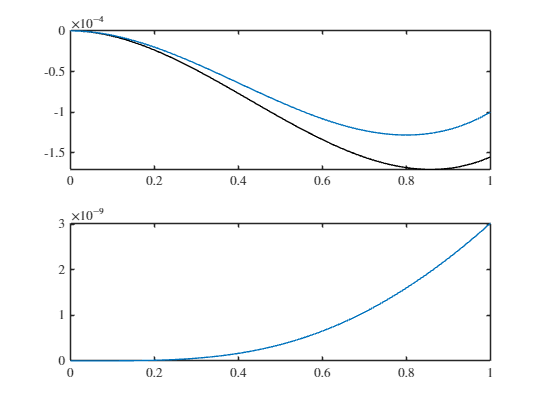


figure
subplot( 2, 1, 1 )
hold on
fplot( U, domain, Color="k" )
fplot( u, domain, SeriesIndex=1 )

subplot( 2, 1, 2 )
fplot( simplify( U - u )^2, domain )

## Spring Mass system

Let's consider one last system.  Thus far we have only explored differential equations that involve a single differential in the governing equation.  But what about differential equations with multiple differentials, such as the second-order linear (ordinary) differental equation that is often a focal point of an undergraduate-level differential equations course:


$$a {u\prime\prime} + b {u\prime} + c u = f$$


Which can be used to model the behavior of a spring-mass system.  For example consider the below system consisting of a heavy object that is placed upon a dampened spring system (sometimes called a spring-dashpot system).

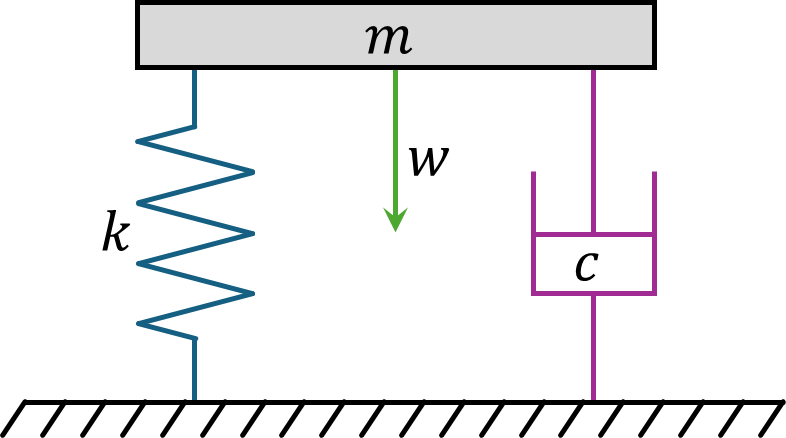

We can reformat the governing equation into one that more clearly relates the physical quantities: mass, $m$; damping coefficient, $c$; spring stiffness, $k$; and weight, $w$:


$$m\frac{d^2 y}{{\textrm{dt}}^2 }+c\frac{\textrm{dy}}{\textrm{dt}}+\textrm{ky}=w$$


In this idealized system we are making a few assumptions:

- The mass of the object is constant -- $m$ is a constant

- The dashpot has a constant damping coefficient -- $c$ is a constant

- The spring is a linear elastic spring -- $k$ is a constant

- The spring and dashpot are themselves of negligible mass compared to the object and their coefficients -- The spring and dashpot do not contribute the weight of the system

- The overall size and displacement of the system, located on Earth's surface, is small -- Constant gravitational field, $w$ is constant

And we will assume the following conditions regarding the system's initial state:

- The object is placed gently upon the spring-dashpot system -- $\frac{\textrm{dy}}{\textrm{dt}}\left(0\right)=0$

- The spring-dashpot system was in a steady-state prior to the object being placed on the system -- $y\left(0\right)=0$

Finally, let's assume the following physical properties of the system:

- The object is a 45 lbf Olympic plate: $m=20\ldotp 4\textrm{kg}$

- System is located at ground-level in Provo, UT: $a_g =9\ldotp 80\;\frac{\mathrm{m}}{{\mathrm{s}}^2 }$, $w=21\ldotp 6\;\mathrm{N}$

- The spring's stiffness is:  $k=29\ldotp 5\times {10}^3 \;\frac{\mathrm{N}}{\mathrm{m}}$

- The damping coefficient is: $c=200\times {10}^3 \;\frac{\mathrm{N}\cdot \;\mathrm{s}}{\mathrm{m}}\;$

function exactSolution = ExactSpringMassEquation( mass, damping, stiffness, force, displacement_constraint, slope_constraint, domain )
syms y(t)
eqn = mass*diff( y, t, 2 ) + damping*diff( y, t, 1 ) + stiffness*diff( y, t, 0 ) == force;
D1y = diff( y, t, 1 );
cond = [     y( domain(1) ) == displacement_constraint, ...
    D1y( domain(1) ) == slope_constraint ];
U(t) = dsolve( eqn, cond );

exactSolution.f = force;
exactSolution.eqn = eqn;
exactSolution.cond = cond;
exactSolution.domain = domain;
exactSolution.U = simplify( U, Steps=10 );
end

The weak form for this problem is a bit trickier than it was for the others, but this is where our previous notion of "change of basis" can help us in the construction.  Consider how we might construct the weak forms in these cases:

#### 
$$k=0,\;c=0$$


"find $y$ such that $m\frac{{\mathrm{d}}^2 y}{{\mathrm{dx}}^2 }$ is the best representation of $f$"


$$\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },m\frac{d^2 y}{{\mathrm{dt}}^2 }\right\rangle =\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },f\right\rangle$$


#### 
$$w=0,\;c=0$$


"find $y$ such that $m\frac{{\mathrm{d}}^2 y}{{\textrm{dx}}^2 }$ is the best representation of $-\mathrm{ky}$"


$$\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },m\frac{d^2 y}{{\mathrm{dt}}^2 }\right\rangle =\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },-\mathrm{ky}\right\rangle$$



$$\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },m\frac{d^2 y}{{\mathrm{dt}}^2 }\right\rangle +\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },\mathrm{ky}\right\rangle =0$$


#### 
$$w=0,k=0$$


"find $y$ such that $m\frac{{\mathrm{d}}^2 y}{{\textrm{dx}}^2 }$ is the best representation of $-c\frac{\mathrm{dy}}{\mathrm{dt}}$"


$$\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },m\frac{d^2 y}{{\mathrm{dt}}^2 }\right\rangle =\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },-c\frac{\mathrm{dy}}{\mathrm{dt}}\right\rangle$$



$$\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },m\frac{d^2 y}{{\mathrm{dt}}^2 }\right\rangle +\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },c\frac{\mathrm{dy}}{\mathrm{dt}}\right\rangle =0$$


Combining the terms we then have


$$\left\langle m\frac{d^2 y}{{\mathrm{dt}}^2 },m\frac{d^2 y}{{\mathrm{dt}}^2 }\right\rangle +\left\langle \frac{d^2 y}{{\mathrm{dt}}^2 },c\frac{\mathrm{dy}}{\mathrm{dt}}\right\rangle +\left\langle \frac{d^2 y}{{\mathrm{dt}}^2 },\mathrm{ky}\right\rangle =\left\langle \frac{d^2 y}{{\mathrm{dt}}^2 },f\right\rangle$$


And then we can consider the initial conditions:

"... while subject to the condition that $\frac{\mathrm{dy}}{\mathrm{dt}}$ is the best representation of $0$ at $t=0$"


$${\left\langle \frac{\mathrm{dy}}{\mathrm{dt}},\frac{\mathrm{dy}}{\mathrm{dt}}\right\rangle }_{\left\lbrack 0\right\rbrack } =\left\langle \frac{\mathrm{dy}}{\mathrm{dt}},0\right\rangle$$


"... while subject to the condition that $y$ is the best representation of $0$ at $t=0$"


$${\left\langle y,y\right\rangle }_{\left\lbrack 0\right\rbrack } =\left\langle y,0\right\rangle$$


function [u, A, F, basis, d] = SpringMassEquation( basis_family, degree, domain, mass, damping, stiffness, force, displacement_constraint, slope_constraint )
variate = symvar( force );
if basis_family == "Trig"
basis = @(deriv) diff( TrigonometricBasis( degree, variate, domain ), variate, deriv );
else
basis = @(deriv) diff( PolynomialBasisFunction( basis_family, degree, variate, domain ), variate, deriv );
end
[A, F] = ApplyGoverningEquations( basis, domain, mass, damping, stiffness, force );
[A, F] = ApplyBoundaryConditions( A, F, basis, domain, displacement_constraint, slope_constraint );
d = A \ F;
u = symfun( transpose( d ) * basis(0), variate );

    function [A, F] = ApplyGoverningEquations( basis, domain, mass, damping, stiffness, force )
        M = int( ( mass * basis(2) ) .* ( mass * transpose( basis(2) ) ), domain );
        C = int( ( mass * basis(2) ) .* ( damping * transpose( basis(1) ) ), domain );
        K = int( ( mass * basis(2) ) .* ( stiffness * transpose( basis(0) ) ), domain );
        A = M + C + K;
        F = int( ( mass * basis(2) ) * force, domain );
    end

    function [A, F] = ApplyBoundaryConditions( A, F, basis, domain, displacement_constraint, slope_constraint )
        [AD, FD] = DisplacementBoundaryCondition( basis, domain, displacement_constraint );
        [AN, FN] = SlopeBoundaryCondition( basis, domain, slope_constraint );
        A = A + AD + AN;
        F = F + FD + FN;
    end

    function [A, F] = DisplacementBoundaryCondition( basis, domain, displacement_constraint )
        A = subs( basis(0) .* transpose( basis(0) ),   symvar( basis(0) ), domain(1) );
        F = subs( basis(0) .* displacement_constraint, symvar( basis(0) ), domain(1) );
    end

    function [A, F] = SlopeBoundaryCondition( basis, domain, slope_constraint )
        A = subs( basis(1) .* transpose( basis(1) ), symvar( basis(0) ), domain(1) );
        F = subs( basis(1) .* slope_constraint,      symvar( basis(0) ), domain(1) );
    end

end

And now we solve the problem.  Note that we are now using a basis of significantly-higher order (degree=12) than we used in previous problems.

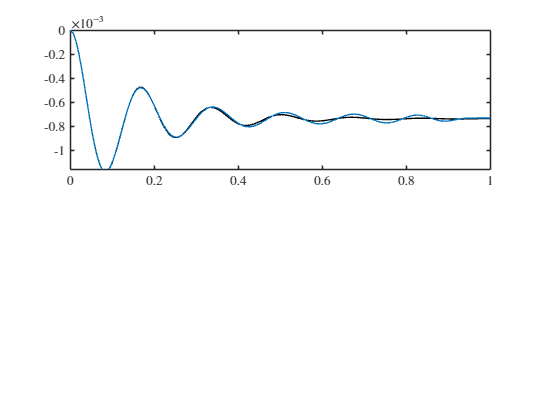

clear

t = sym( "t", "real" );
mass = sym( 20.4 );
damping = sym( 250 );
stiffness = sym( 29.5e3 );
force(t) = -sym( 21.6 ) * t^0;
h = sym( 0 );
g = sym( 0 );

domain = [0, 1];
degree = 12;
basis_family = "Monomial";

U = ExactSpringMassEquation( mass, damping, stiffness, force, g, h, domain ).U;
u = SpringMassEquation( basis_family, degree, domain, mass, damping, stiffness, force, g, h );


l2_error = ComputeL2Error( U, u, domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

figure
subplot( 2, 1, 1 )
hold on
fplot( U, domain, Color="k" )

Elapsed time: 4.5


fplot( u, domain, SeriesIndex=1 )

subplot( 2, 1, 2 )
fplot( simplify( U - u ), domain )

While not perfect, our approach has yielded a fairly accurate solution to this problem.  We observe, however, that it's not yet quite clear what value of deflection our system will settle at and we're already at a quite high polynomial degree.  Already this calculation is quite expensive, on my computer taking around one or two seconds:

time_fun = @()SpringMassEquation( basis_family, degree, domain, mass, damping, stiffness, force, g, h );
t_elapsed = timeit( time_fun, 1 );
disp( "Elapsed time: " + num2str( t_elapsed, 2 ) )

Now, one or two seconds may not seem like a long time, but consider the simplicity of this problem: a single mass on a single spring and dashpot and we've not even *really* solved the problem! So how might we be able to improve upon our method?  Let's start looking at that in the next lecture!